% Definir la variable simbólica para la función de transferencia
s = tf('s');

% Funciones de transferencia individuales
FdT_Planta = 1/(7.5*s^2 + 6.5*s + 1);         % Funcion de transferencia de la planta
FdT_Sensor = 0.01;                            % Funcion de transferencia del sensor
FdT_Ventilador = -0.0038/(s + 0.007);         % Funcion de transferencia del ventilador
FdT_Comparador = 16.67;                       % Funcion de transferencia del comparador
FdT_Inversor = -1;                            % Inversor 

%Utilizando el algebra de bloques obtenemos la fdt global
G=FdT_Planta*FdT_Ventilador*FdT_Comparador*FdT_Inversor;
H=FdT_Sensor;

%Funcion de transferencia global
FdT_Global=feedback(G,H);

% Función de transferencia global original
disp('La función de transferencia global original es:');

La función de transferencia global original es:


FdT_Global

FdT_Global =
 
                  0.06335
  ----------------------------------------
  7.5 s^3 + 6.553 s^2 + 1.046 s + 0.007633
 
Continuous-time transfer function.



% Definir la función de transferencia a lazo abireto (GH)
GH = G*H

GH =
 
                0.0006335
  -------------------------------------
  7.5 s^3 + 6.553 s^2 + 1.046 s + 0.007
 
Continuous-time transfer function.




% Calcular y mostrar los ceros de la función de transferencia a lazo abierto
disp('Ceros de la función de transferencia:');

Ceros de la función de transferencia:


zero_GH = zero(GH);
disp(zero_GH);

% Calcular y mostrar los polos de la función de transferencia a lazo abierto
disp('Polos de la función de transferencia:');

Polos de la función de transferencia:


pole_GH = pole(GH);
disp(pole_GH);

   -0.6667
   -0.2000
   -0.0070




% Graficar el lugar de raíces de la función de transferencia
figure;
rlocus(GH);
grid on;

%El sistema es marginalmente estable, para k<11
rlocfind(GH);

Select a point in the graphics window


selected_point = 0.1499 + 0.6935i

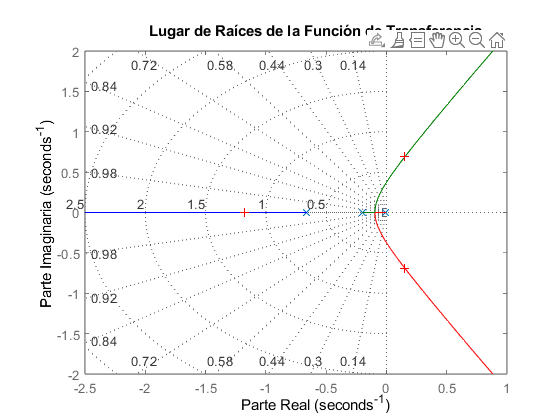

grid on;

title('Lugar de Raíces de la Función de Transferencia');
xlabel('Parte Real');
ylabel('Parte Imaginaria');

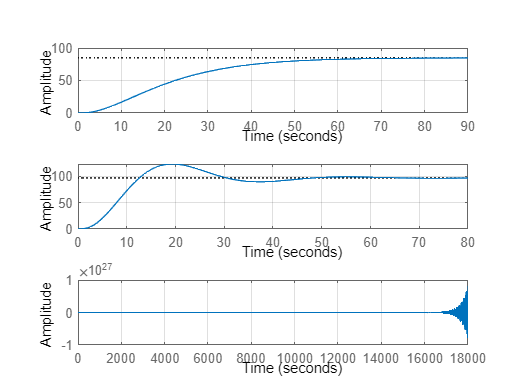

%Definimos distintos valores de k para simular la respuesta 
k1 = 62;
k2 = 300;
k3=1500;

%Por la ubicacion del polo dominante resulta imposible una compensacion
%solo proporcional ya que el polo dominante esta muy cerca del origen y
%hace al sistema muy lento

% Crear un figure con tres subplots
figure;

% Primer subplot: Respuesta para k1
subplot(3, 1, 1);
step(feedback(k1*G,H));
title('');
xlabel('Time')
ylabel('Amplitude')
grid on;

% Segundo subplot: Respuesta para k2
subplot(3, 1, 2);
step(feedback(k2*G,H));
title('');
xlabel('Time')
ylabel('Amplitude')
grid on;

% Segundo subplot: Respuesta para k3
subplot(3, 1, 3);
step(feedback(k3*G,H));
title('');
xlabel('Time')
ylabel('Amplitude')
grid on;

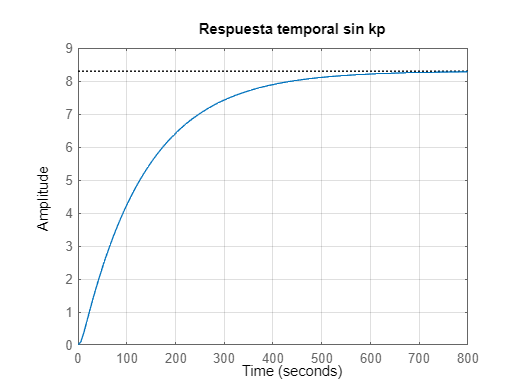


figure;
step(feedback(G,H));
title('Respuesta temporal sin kp');
xlabel('Time')
ylabel('Amplitude')
grid on